## Example wavelet analysis

### Add dependencies

addpath('W:\LABanalysis\SilviaProjectCode\wavelet')
addpath('W:\LABanalysis\SilviaProjectCode\Tools') % just needed for write_csvfile
addpath(genpath('W:\LABanalysis\cluster_cutting\Newest MClust (microvolts, history logging)')); %required for reading the LFPs

addpath('W:\LABanalysis\SilviaProjectCode');
addpath(genpath('W:\LABanalysis\SilviaProjectCode'));

addpath('W:\LABanalysis\SilviaProjectCode\Tools');

### Import example file

eegfilename = fullfile('W:\Lorena\Recordings\1433\2025-05-19_14-07-15_day1\CSC1.ncs');
fprintf('Reading: %s\n', eegfilename);

Reading: W:\Lorena\Recordings\1433\2025-05-19_14-07-15_day1\CSC1.ncs


[eeg, sFreq] = readCRTsd(eegfilename);

Reading 198864 CR records
ts[0]= 1.74766e+13 
ChanNum[0]= 0 
sampFreq[0]= 32000 
dwNumValid[0] = 512


%L = detectHFOs.getMultiCSC(num2str(cellayerCH(i)),1);
lfp.samp = Data(eeg)*-1; %flip data;
%lfp.sFreq = sFreq;
lfp.samp=downsample(lfp.samp,16);  %downsample; take every 16th data point
lfp.ts = Range(eeg);
lfp.ts = downsample(lfp.ts,16);
lfp.sampFreq = sFreq/16;

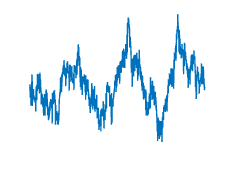

clf, hold off
plot(lfp.samp(1:1000))
axis off

lfp

lfp = struct with fields:
        samp: [6363648×1 double]
          ts: [6363648×1 double]
    sampFreq: 2000


### Morlet wavelet analysis

% Parameters
fs =  lfp.sampFreq; %eegx_region.Fs; %lfp.sampFreq;
lfp_ex = lfp.samp(1:2000); %eegx_region.d; %lfp.samp(1:2000);
freq_band_theta = [6 12];      
n_cycles = 6;         
time_vec = (0:length(lfp_ex)-1) / fs;

theta_phase = get_phase_LFP(lfp_ex, fs, freq_band_theta, n_cycles);

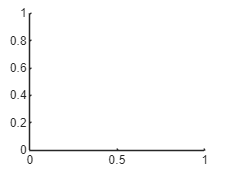

clf, hold off

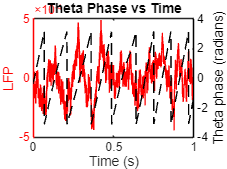

figure;
ax = gca();
yyaxis left
plot(time_vec, lfp_ex, Color="red")
ylabel('LFP');
yyaxis right
plot(time_vec, theta_phase, LineStyle="--",Color="k");
xlabel('Time (s)');
ylabel('Theta phase (radians)');
ax.YAxis(1).Color = "red";
ax.YAxis(2).Color = "k";
title('Theta Phase vs Time');

Calculate ITTP

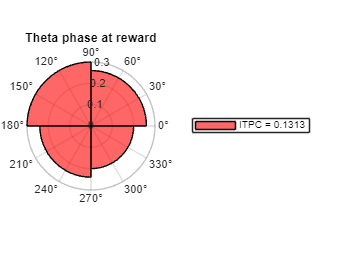

reward_time_ind = randi([300, 1000], 1, 50);
theta_ITPC = ITPC(theta_phase(reward_time_ind));
clf, hold off
polarhistogram(theta_phase(reward_time_ind), Normalization="probability",FaceColor="red")
title("Theta phase at reward")
legend("ITPC = " + num2str(theta_ITPC))

ITTP with respect to time

time_window = [-0.1,0.1];
time_window_ind = time_window(1)*fs: 1 : time_window(2)*fs;
theta_ITPC_t = zeros(length(time_window_ind), 1);

ti = 0;
for t = time_window_ind
    ti = ti + 1;
    theta_ITPC_t(ti) = ITPC(theta_phase(reward_time_ind + t));
end

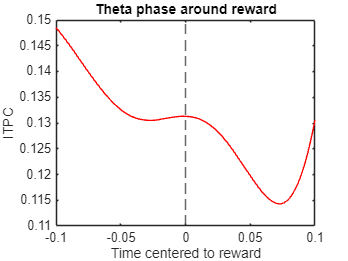

time_window_vec = time_window(1):1/fs:time_window(2);
clf
plot(time_window_vec, theta_ITPC_t, color="red")
xline(0,LineStyle="--")
xlabel("Time centered to reward")
ylabel("ITPC")
title("Theta phase around reward")
hold off

### -------------------------------------------------

### Using anglewwd2 function

opt.wavelet.dsrate = 16;  %Used for spectogramm
opt.wavelet.smoothingWin = 20;
opt.wavelet.freqRes = 20;
[angle_, t, f, bandSpecgramFun] = anglewwd2(lfp_ex, lfp.sampFreq, 4, 300, opt.wavelet);

[~, theta_indx] = min(abs(f-theta_freq));
clf, hold off
plot(angle_(:,1))
hold on
plot(angle_(:,2))

ans = categorical
     Control 


Random tests

colors(1,:)

ans =     0.1400    0.8500    0.7100




function phase_LFP = get_phase_LFP(lfp, fs, freq_band, n_cycles)
    % Inputs:
    % lfp: 1d array with the LFP signal
    % fs: sampling time_vec
    % freq_band: desired freq_band [start, end]
    % n_cycles: number of cycles for the morlet wavelet
    % 
    % Outputs:
    % phase_LFP: phase of the LFP for each time bin
    
    % Morlet wavelet
    center_freq = round(mean(freq_band));              

    w_len = 6 / center_freq; 
    t = -w_len/2 : 1/fs : w_len/2;
    s = n_cycles / (2*pi*center_freq); % std of Gaussian
    morlet_wavelet = exp(2*1i*pi*center_freq*t) .* exp(-t.^2/(2*s^2));
    
    % Convolve LFP with Morlet wavelet and extract phase
    conv_result = conv(lfp, morlet_wavelet, 'same');
    phase_LFP = angle(conv_result);    

end

function itpc = ITPC(phase)
    % Inputs:
    % phase: an array shape (trials)
    %
    % Outputs:
    % itpc: inter trial phase clustering metric

    itpc = abs(mean(exp(phase*1i)));

end


function [angle_, t, f, bandSpecgramFun] = anglewwd2(eeg, sampFreq, fpassLow, fpassHigh, params)
    % SPECGRAMWWD(eeg, sampFreq, fpassLow, fpassHigh, params) spectrogram by
    % wavelets with downsampling (a user friendy interface to contwt())
    %
    % INPUT:
    %	eeg
    %		Double array of raw EEG signal
    %
    %	sampFreq
    %		Sample rate of the EEG signal (in Hz)
    %
    %	fpassLow
    %		Lowest frequency requested for band-pass filter
    %
    %	fpassHigh
    %		Highest frequency requested for band-pass filter
    % 
    %	params (OPTIONAL)
    %		Parameters for downsampling and smoothing
    %
    %		Can have the following fields:
    %
    %			dsrate: down sample by this number of points
    %					this is applied after the wavelet transform, so use
    %					this to save memory for storing the resulting
    %					spectrogram. Default is 25.
    %
    %			minNyquist:
    %					retain at least this number of samples per fastest
    %					frequency in order to perform wavelet transform. This,
    %					in a way, is a "pre-downsampling". Default is 5, if the
    %					requested fpassHigh is at least 1/5 of sampling rate.
    %
    %			smoothingWin:
    %					Will be used as the smoothing filter kernel width for
    %					the downsampled spectrogram (in seconds).
    % 
    %			freqRes:
    %					The resolution in the frequency axis. The higher the
    %					number, the closer lying the frequency definition.
    %					Higher values correspond to finer resolutions, which in
    %					turn requires higher amount of memory.
    %					Default is 50.
    %					(TODO: change this such that user specifies the number
    %					of frequency bands, rather than an arbitrary number.)
    %
    %
    % OUTPUT:
    %	SPG:
    %		The spectrogram. A matrix whose columns are the spectral power
    %		density across time samples and whose rows are the power profile
    %		within a narrow frequency band, corresponding to the entry in 'f'.
    %		The frequency axis will be logarithmic.
    % 
    %	t
    %		The time points. Can be used as a label for plotting SPG, or
    %		restricting SPG to certain epochs.
    % 
    %	f
    %		The frequencies. Can be used as a label for plotting SPG, or
    %		pulling out a certain band from within SPG. The scale is
    %		logarithmic.
    %
    %	bandSpecgramFun(low, hi)
    %		Function handle. Accepts as input two arguments, low and hi, and
    %		returns the chunk of SPG that most closely lies within [low, hi]
    %		frequency band.
    %		USAGE: [SPG_band, f_band] = bandSpecgramFun(lowFreq, hiFreq);
    %
    % External (non-MATLAB) calls: closestPoint(), contwt()
    
    % Siavash Ahmadi
    % University of California, San Diego
    % January 28, 2015
    
    afterdsrate = 25;
    minNyquist = 5; % at least this many samples for the highest frequency requested
    smoothingWin = 20;
    freqRes = 50;
    if exist('params', 'var')
	    if isfield(params, 'dsrate')
		    afterdsrate = params.dsrate;
	    end
	    if isfield(params, 'minNyquist')
		    minNyquist = params.minNyquist;
	    end
	    if isfield(params, 'smoothingWin')
		    smoothingWin = params.smoothingWin;
	    end
	    if isfield(params, 'freqRes')
		    freqRes = params.freqRes;
	    end
    end
    if fpassHigh > sampFreq/2
	    warning(['Nyquist frequency is ' num2str(sampFreq/2) '. Using this as high frequency cutoff.'])
	    fpassHigh = sampFreq/2;
    end
    if minNyquist < 2
	    minNyquist = 2; % at least two samples needed per highest frequency according to Nyquist-Shannon sampling theorem
    end
    if minNyquist > sampFreq/fpassHigh
	    minNyquist = floor(sampFreq/fpassHigh);
	    if exist('params', 'var') && isfield(params, 'minNyquist')
		    warning(['minNyquist requested is too high. Given requested low-pass cutoff, maximum possible is ' num2str(minNyquist) ', which will be used.'])
	    end
    end
    
    dsrate = floor(sampFreq/(minNyquist*fpassHigh));
    sr_ds = sampFreq/dsrate;
    eeg_ds = downsample(eeg, dsrate);
    dt = 1/sr_ds;
    finestScale = 1/fpassHigh;	% upper cutoff frequency
    df = log2(fpassHigh/fpassLow)/round(log2(fpassHigh/fpassLow))/freqRes;% frequency resolution
    numScales = round(log2(fpassHigh/fpassLow)/df);
    
    [wave, ~, scale] = contwt(eeg_ds,dt,1,df,finestScale,numScales, 'morlet');
    
    f = 1./scale;
    
    dt = dsrate*afterdsrate/sampFreq;


    angle_raw = downsample(angle(wave), afterdsrate);
    angle_smooth = smooth(angle_raw, size(angle_raw, 1)/(smoothingWin/dt));
    angle_ = reshape(angle_smooth, size(angle_raw, 1), size(angle_raw, 2))';
    t = dt:dt:length(angle_)*dt;
    
    bandSpecgramFun = @(low, hi) getFreqBandSpecgram(angle_, f, low, hi);
end

function [S, f] = getFreqBandSpecgram(SPG, f, low, hi)
    hi_ind = closestPoint(fliplr(f), 1:length(f), hi);
    low_ind = closestPoint(fliplr(f), 1:length(f), low);
    
    S = SPG(end-hi_ind+1:end-low_ind+1, :);
    f = f(end-hi_ind+1:end-low_ind+1);
end